#     Ecuaciones lineales de primer orden  

# Problemas de valor inicial

## Adaptive and  Multistep methods 

## Stiff systems and Implicit methods

### Epidemia

The following ODEs have been proposed as a model of an epidemic:


$$\frac{\mathrm{d}}{\mathrm{d}t}S=-a\;S\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}I=a\;S\;I-r\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}R=r\;I$$


where S = the susceptible individuals, I = the infected, R = the recovered, a = the infection rate, and r = the recovery rate. A city has 10,000 people, all of whom are susceptible. If a single infectious individual enters the city at t = 0, compute the progression of the epidemic until the number of infected individuals falls below 10. Use the following parameters: a = 0.002/(person · week) and r = 0.15/d.

Develop time-series plots of all the state variables.

Suppose that after recovery, there is a loss of immunity that causes recovered individuals to become susceptible.

This reinfection mechanism can be computed as ρR, where ρ = the reinfection rate. Modify the model to include this mechanism and repeat the computations using ρ = 0.03/d.

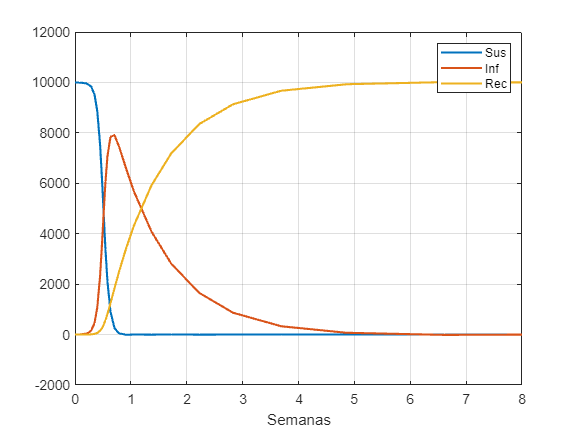

t0 = 0;
tf = 8;
tol = 1e-3;

p = 10000;
a = 0.002;
r = 1.05;
o = 0.21;

f = @(t,y) [-a*y(1)*y(2);
            a*y(1)*y(2)-r*y(2);
            r*y(2)];
y0 = [p-1;1;0];

[Tiempo,Valores] = TerPar_ode23MVC(f,y0,t0,tf,tol);

plot(Tiempo,Valores,"LineWidth",1.5)
grid on
xlabel("Semanas")
legend("Sus", "Inf", "Rec")

### Variable step size

Solve the following ODE from t=0 to 4, where y(0)=0.5. Obtain the solution for a relative tolerance of ${10}^{-5}$:


$$\frac{\mathrm{d}}{\mathrm{d}t}y=10e^{-\left({\left(t-2\right)}^2 /2{\left(0\ldotp 075\right)}^2 \right)} -0\ldotp 6y$$


% Ejemplo 21.2 Chapra (3ed)
f = @(t,y) 10*exp(-(t-2)^2/(2*0.075^2)) - 0.6*y;
y0 = 0.5;
t0 = 0;
tf = 4;
tol = 1e-5

tol = 1.0000e-05

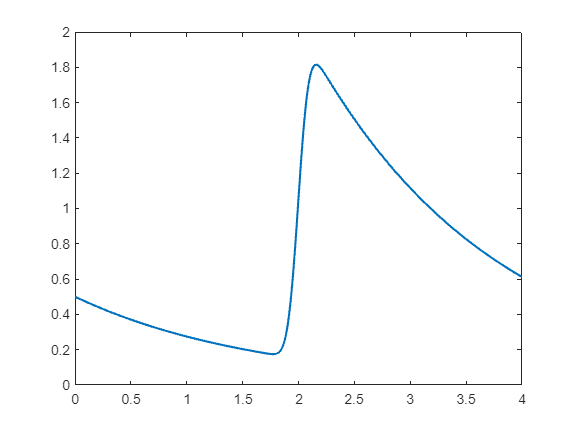


[Tiempo,Valores] = TerPar_ode23MVC(f,y0,t0,tf,tol);
plot(Tiempo,Valores,"LineWidth",1.5)

Solve the initial value problem within a relative tolerance of ${10}^{-6}$:

$y^{\prime } =t\;y+t^3$         $y\left(0\right)=1$          t in [0,1]

f = @(t,y) t*y+t^3;
y0 = 1;
t0 = 0;
tf = 1;
tol = 1e-6

tol = 1.0000e-06

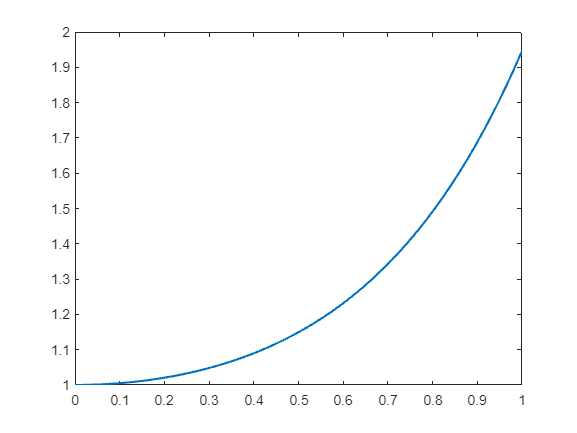


[Tiempo,Valores] = TerPar_ode23MVC(f,y0,t0,tf,tol);
plot(Tiempo,Valores,"LineWidth",1.5)

### Mutistep 

Solve the initial value problem:

$y^{\prime } =\frac{1}{2}\left(1+x\right)y^2$         $y\;\left(0\right)=1$          t in [0,1]

t0 = 0;
tf = 1;
h = 0.01;
f = @(t,y) (1+t)*y^2/2;
y0 = 1;

[t,y] = odeMilnes(f,y0,t0,tf,h);
[~,y2] = ode45(f, t0:h:tf, y0);
plot(t,[y y2])
legend ("Milnes", "45")

Solve the initial value problem:

$y^{\prime } =\frac{-2y}{1+t}$         $y\;\left(0\right)=2$          t in [0,2.5]

t0 = 0;
tf = 2.5;
h = 0.01;
f = @(t,y) -2*y/(1+t);
y0 = 2;

[t,y] = odeMilnes(f,y0,t0,tf,h);
[~,y2] = ode45(f, t0:h:tf, y0);
%En este ejemplo ode45 tarda mucho
plot(t,[y y2])
legend ("Milnes", "45")

### Stiff equations

A problem is stiff if the solution being sought varies slowly, but there are nearby solutions that vary rapidly, so the numerical method must take small steps to obtain satisfactory results.

Apply the Euler and Backward Euler methods to the initial value problem

$y^{\prime } =y+8y^2 -9y^3$         $y\;\left(0\right)=0\ldotp 5$          t in [0,3]

% ode15s
% ode45
% Euler

t0 = 0;
tf = 3;
h = 0.25;
f = @(t,y) y+8*y^2-9*y^3;
y0 = .5;

[t,y1] = odeEulerBack(f,y0,t0,tf,h);
[~,y2] = ode15s(f, t0:h:tf, y0);
[~,y3] = ode45(f, t0:h:tf, y0);
[~,y4] = odeEuler(f,y0,t0,tf,h);
plot(t,[y1 y2 y3 y4'])
grid on
legend ("EulerBack","15s", "45", "Euler")

ODE23 personal

function [t, y] = ode23P(f,y0,t0,tf,tol)
     pow = 1/3;
    RelTol = tol;
    iMax = 100;
    t = t0;
    y = y0;
    h = (tf-t0)/100;
    condicion = true;
    i = 1;
    vecT = t;
    vecY = y;
    
    while condicion
        s1 = f(t,y);
        s2 = f(t+h/2, y+h*s1/2);
        s3 = f(t+3*h/4, y+h*3*s2/4);
        tNext = t + h;
        yNext = y + h*(2*s1 + 3*s2 + 4*s3)/9;
        s4 = f(tNext, yNext);
        e = h*(-5*s1 + 6*s2 + 8*s3 - 9*s4)/72;
        err = norm(e/yNext, inf);
        if err<RelTol
            vecT = [vecT, tNext];
            vecY = [vecY, yNext];
            t = tNext;
            y = yNext;
            i = i+1;
        end
        s = (RelTol/err)^pow;
        h = s*h;
        
        if 1.1*abs(h)>= abs(tf-t(end))
            h = tf-t(end);
        end
        
        condicion = tNext<tf && i<iMax;
    end
    t = vecT';
    y = vecY';
end


function [t,y] = odeMilnes(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    [~,y] = odeRK4(f,y0,t0,t0+3*h,h);
    y = y';
    
    for i=4:n-1
        yp = y(i-3)+4*h/3*(2*f(t(i),y(:,i))-f(t(i-1),y(:,i-1))+2*f(t(i-2),y(:,i-2)));
        y(:,i+1) = y(:,i-1)+h/3*(f(t(i-1),y(:,i-1))+4*f(t(i),y(i))+f(t(i+1),yp));
    end
    t = t';
    y = y';
end


function [t,y] = odeEulerBack(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    y = zeros(length(y0),n);
    y(:,1) = y0;
    i=1;
    
    for i=1:n-1
        g = @(z) z-y(i)-f(t(i+1),z)*h;
        [y(:,i+1),~] = newtonRaphson(g,y(:,i),y(:,i));
    end
    y = y';
    t = t';
end